load("Lab1_TXSig.mat");

# Part 1

## (1) 16-QAM constellation diagram

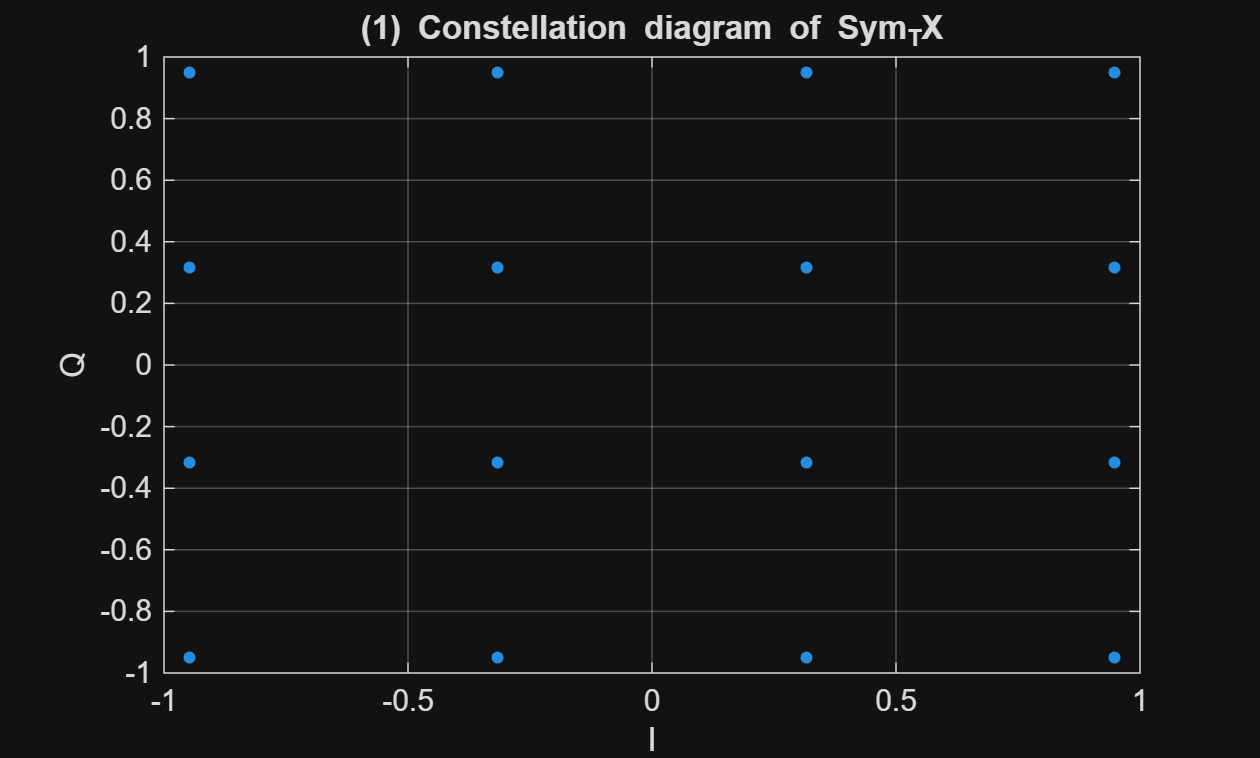

figure;
plot(real(Sym_TX), imag(Sym_TX), '.', "MarkerSize", 12);
grid on;
xlabel('I')
ylabel('Q')
title('(1) Constellation diagram of Sym_TX')

% xline(0, 'k-', 'LineWidth', 2); % vertical axis at x=0
% yline(0, 'k-', 'LineWidth', 2); % horizontal axis at y=0

## (2) FFT of Sym_TX and Sig_BB_TX_Upsamp

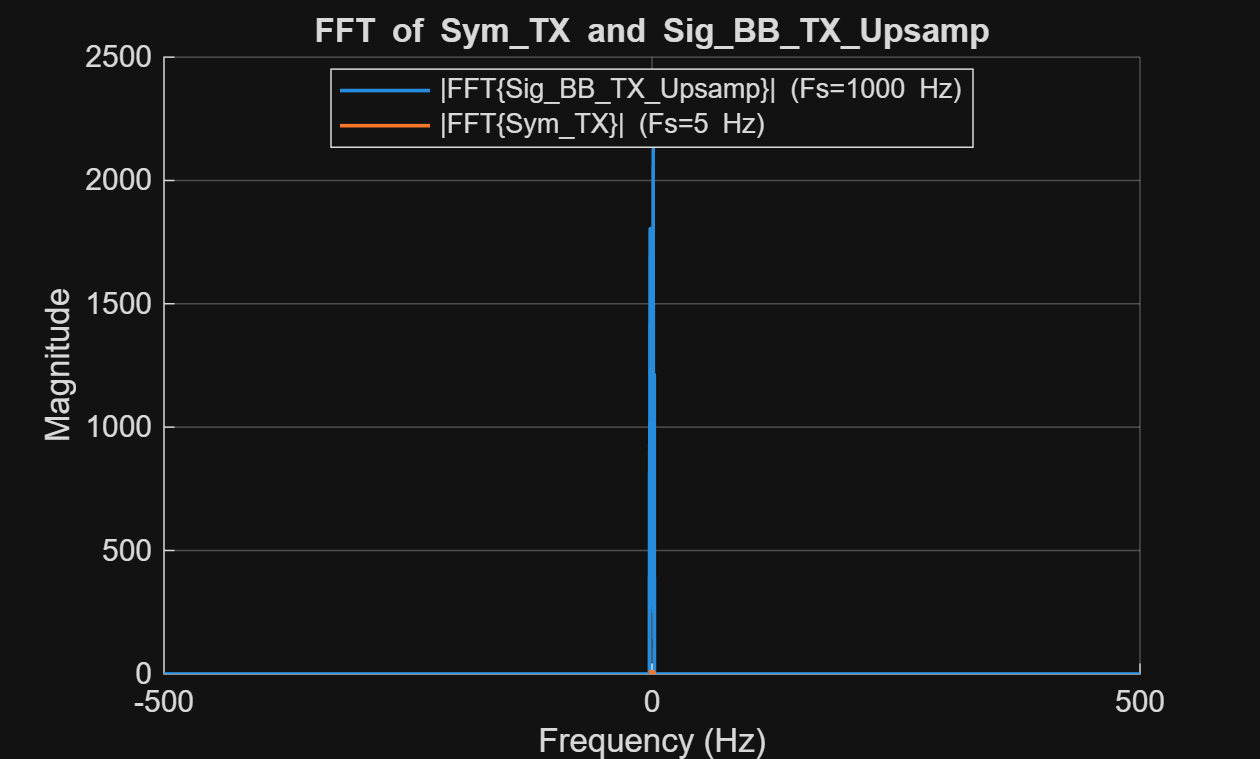

N1 = 32;
N2 = N1*(1000/5);
Fs1 = 5;
Fs2 = 1000;
X_sym = fftshift(fft(Sym_TX, N1));
X_sig_upsamp = fftshift(fft(Sig_BB_TX_Upsamp, N2));
f1  = (-N1/2:N1/2-1)*(Fs1/N1);
f2 = (-N2/2:N2/2-1)*(Fs2/N2);

figure; hold on; grid on;
plot(f2, abs(X_sig_upsamp), 'LineWidth', 1.2);
plot(f1, abs(X_sym), 'LineWidth', 1.2);

xlim([-500 500]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of Sym\_TX and Sig\_BB\_TX\_Upsamp');
legend('|FFT\{Sig\_BB\_TX\_Upsamp\}| (Fs=1000 Hz)', ...
       '|FFT\{Sym\_TX\}| (Fs=5 Hz)', ...
       'Location', 'best');

## (3) Zoomed in 5Hz

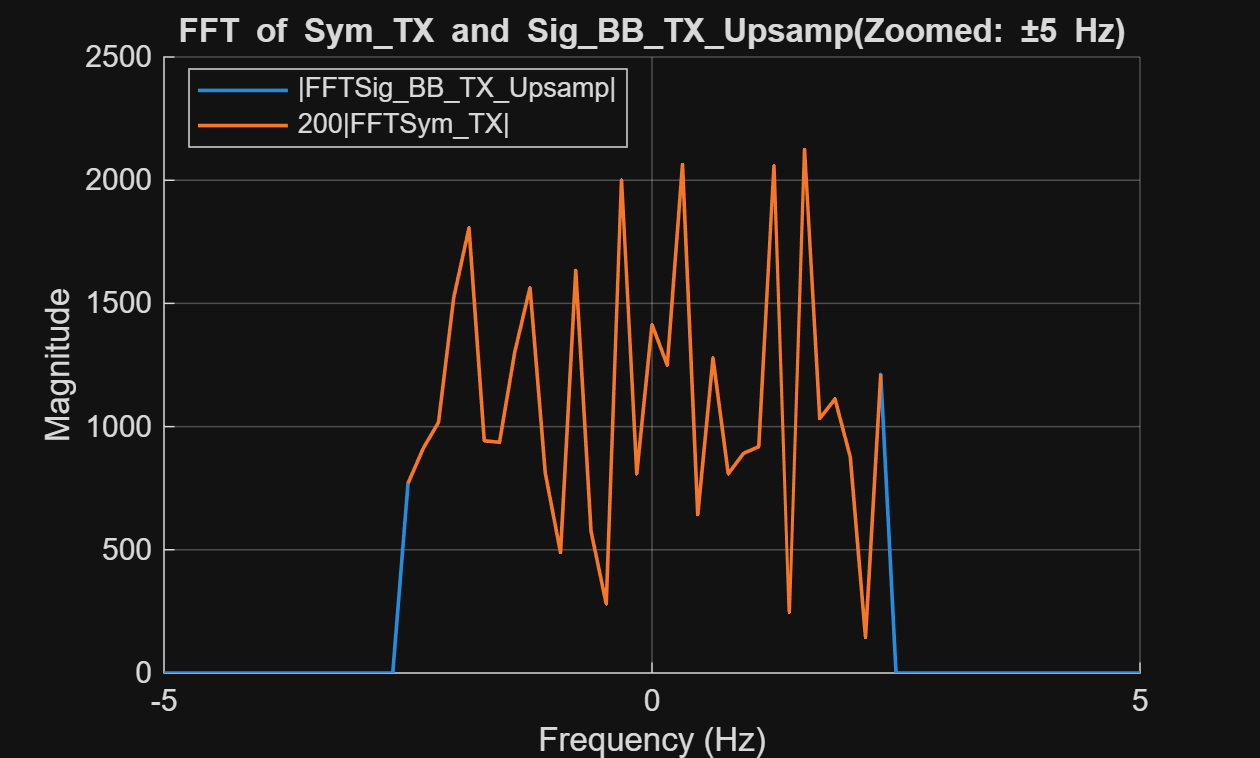

figure; hold on; grid on;
plot(f2, abs(X_sig_upsamp), 'LineWidth', 1.2);
plot(f1, 200*abs(X_sym), 'LineWidth', 1.2);
xlim([-5 5]);
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('FFT of Sym\_TX and Sig\_BB\_TX\_Upsamp(Zoomed: ±5 Hz)');
legend('|FFT{Sig\_BB\_TX\_Upsamp}|', '200|FFT{Sym\_TX}|', 'Location', 'best');

threshhold = max(abs(X_sig_upsamp))/1000;
inBWindices = abs(X_sig_upsamp) >= threshhold;
inBWfreqs = f2(inBWindices);
BW = max(inBWfreqs) - min(inBWfreqs);
fprintf('Bandwidth = %f\n', BW);

Bandwidth = 4.843750


## (4) Upconvert the BB signal to carrier frequency 

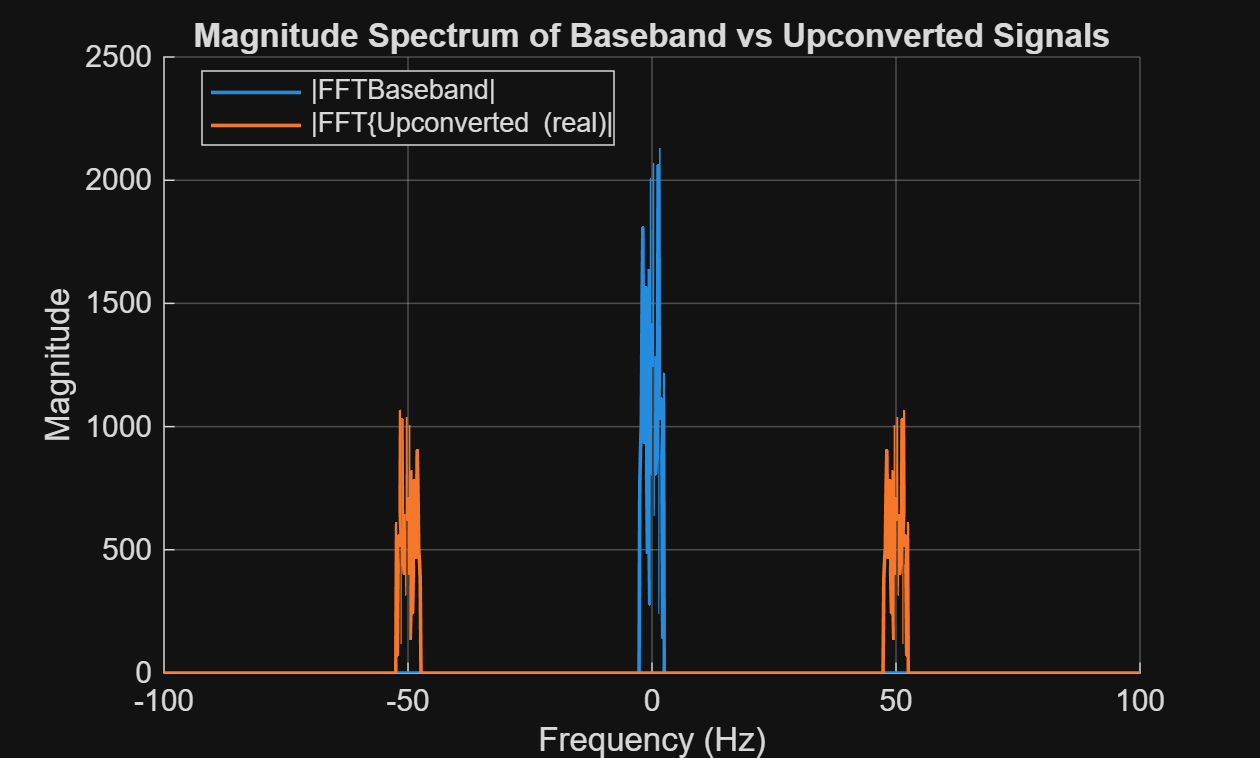

N = 6400;
Fs = 1000;
fc = 50;
Sig_upconv = Sig_BB_TX_Upsamp .* exp(1j*2*pi*fc*tSamp).';
Sig_upconv_real = real(Sig_upconv);

f = (-N/2:N/2-1)*(Fs/N);
X_sig_baseband = fftshift(fft(Sig_BB_TX_Upsamp));
X_sig_upconv = fftshift(fft(Sig_upconv_real));

figure; hold on; grid on;
plot(f, abs(X_sig_baseband), 'LineWidth', 1.2);
plot(f, abs(X_sig_upconv), 'LineWidth', 1.2);
xlim([-100 100]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Baseband vs Upconverted Signals');
legend('|FFT{Baseband}|', '|FFT{Upconverted (real)|', 'Location', 'best');

The upconverted signal is around +- 50 Hz.

## (5) Time domain signal of Sig_BB_TX_Upsamp and upconverted version

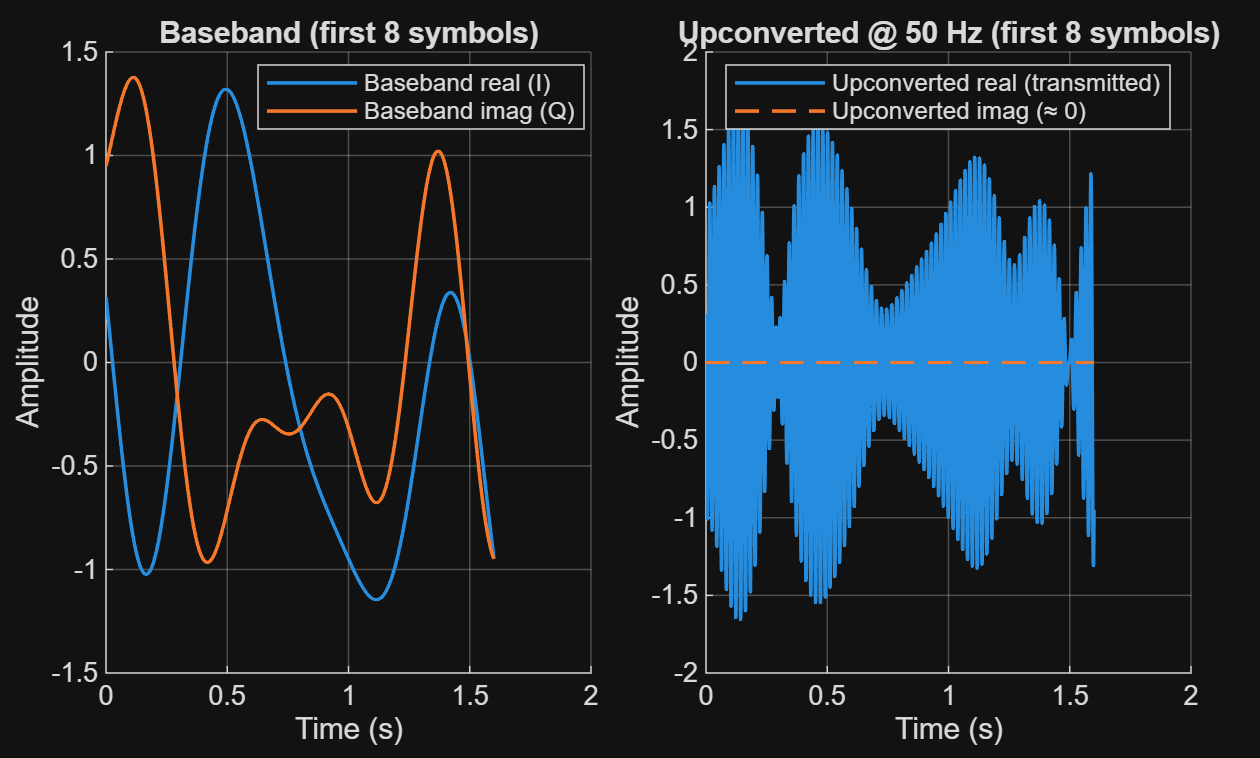


Rs  = 5;                   % symbol rate (Hz)
Tsym = 1/Rs;               % 0.2 s
Tview = 8*Tsym;            % first 8 symbols = 1.6 s

%true signal is real
xRF_real = real( Sig_upconv_real );
xRF_imag = imag(Sig_upconv_real);    % transmitted signal is purely real

%first 8 symbols for plotting
t0   = tSamp(1);
idx  = (tSamp >= t0) & (tSamp <= t0 + Tview);

% --- Plot: side-by-side for clarity ---
tiledlayout(1,2, 'Padding', 'compact', 'TileSpacing', 'compact');

% Left: baseband I/Q
nexttile; hold on; grid on;
plot(tSamp(idx), real(Sig_BB_TX_Upsamp(idx)), 'LineWidth', 1.2);
plot(tSamp(idx), imag(Sig_BB_TX_Upsamp(idx)), 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Baseband (first 8 symbols)');
legend('Baseband real (I)', 'Baseband imag (Q)', 'Location', 'best');

% Right: upconverted (real passband)
nexttile; hold on; grid on;
plot(tSamp(idx), xRF_real(idx), 'LineWidth', 1.2);
plot(tSamp(idx), xRF_imag(idx), '--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Upconverted @ 50 Hz (first 8 symbols)');
legend('Upconverted real (transmitted)', 'Upconverted imag (≈ 0)', 'Location', 'best');

## (6) Minimum cutoff frequency for the lowpass filter

Need to preserve the baseband bandwidth

cutoff = max(max(inBWfreqs), abs(min(inBWfreqs)));
% cutoff = BW/2;
fprintf("Minimum cutoff frequency = %f Hz\n", cutoff);

Minimum cutoff frequency = 2.500000 Hz


## (7) Downsampling process

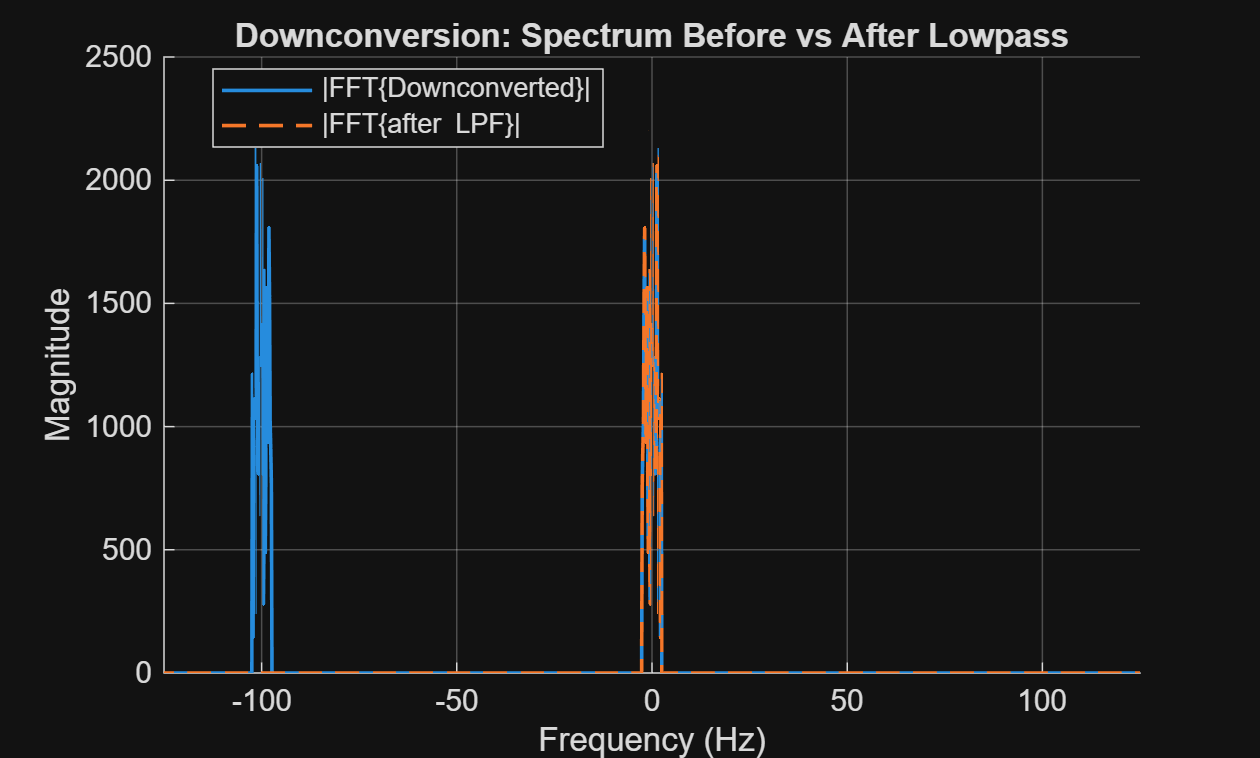

Sig_downconv = Sig_upconv_real .* exp(-1j*2*pi*fc*tSamp).' *2;

cutoff = 2.5;
f = (-N/2:N/2-1) * (Fs/N);
cutoff_mask = abs(f) <= cutoff;

X_sig_downconv = fftshift(fft(Sig_downconv));
X_sig_downconv_lowpassed = X_sig_downconv .* cutoff_mask.';

figure; hold on; grid on;
plot(f, abs(X_sig_downconv), 'LineWidth', 1.2);
plot(f, abs(X_sig_downconv_lowpassed), '--', 'LineWidth', 1.2);
xlim([-125 125]);                        
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Downconversion: Spectrum Before vs After Lowpass');
legend('|FFT\{Downconverted\}|', '|FFT\{after LPF\}|', 'Location', 'best');

## (8) Downconverted+Lowpassed v.s. Original Spectrum

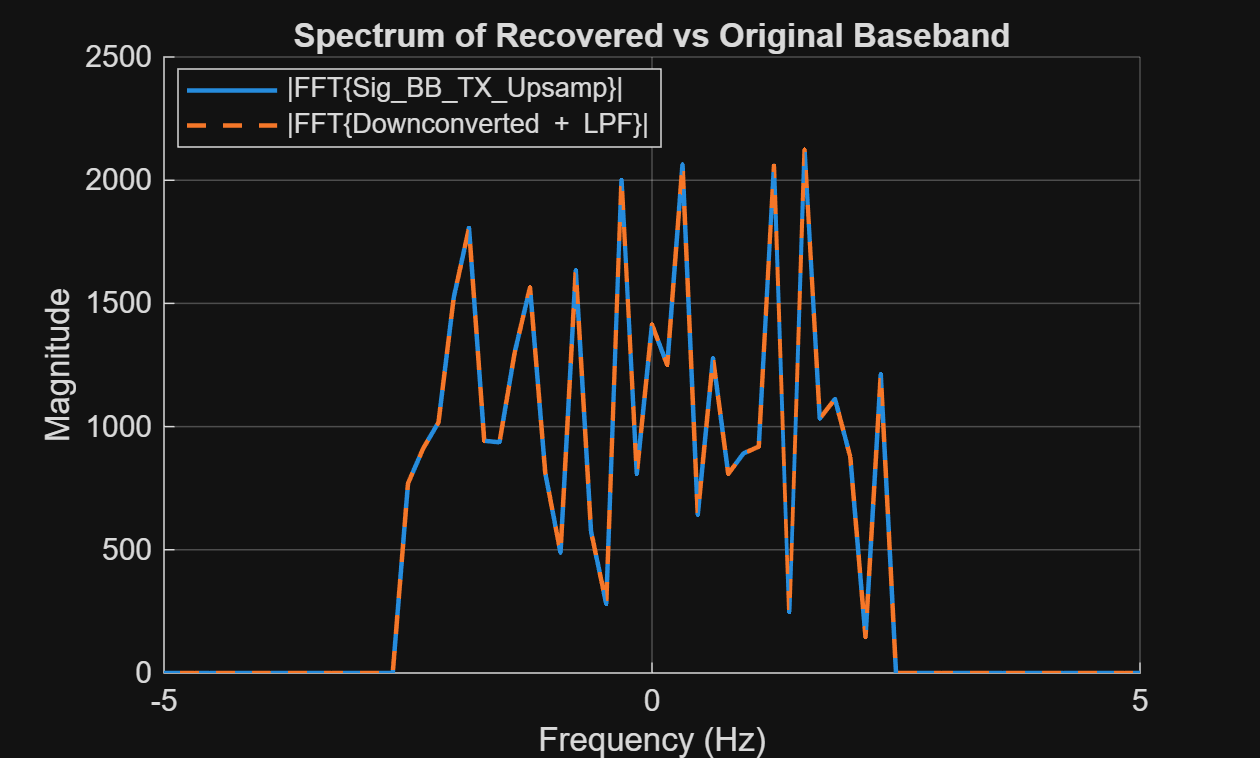

figure; hold on; grid on;
plot(f, abs(X_sig_upsamp), 'LineWidth', 1.5);
plot(f, abs(X_sig_downconv_lowpassed), '--', 'LineWidth', 1.5);
xlim([-5 5]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectrum of Recovered vs Original Baseband');
legend('|FFT\{Sig\_BB\_TX\_Upsamp\}|', '|FFT\{Downconverted + LPF\}|', ...
       'Location', 'best');

## (9) Downconverted+Lowpassed v.s. Original time domain signal

Sig_downconv_lowpassed = ifft(ifftshift(X_sig_downconv_lowpassed));

N = 6400;

% --- Quick quantitative check (print RMSEs) ---
rmse_real = sqrt(mean((real(Sig_BB_TX_Upsamp)-real(Sig_downconv_lowpassed)).^2));
rmse_imag = sqrt(mean((imag(Sig_BB_TX_Upsamp)-imag(Sig_downconv_lowpassed)).^2));
fprintf('RMSE(real): %.3e,  RMSE(imag): %.3e\n', rmse_real, rmse_imag);

RMSE(real): 8.773e-15,  RMSE(imag): 6.873e-15


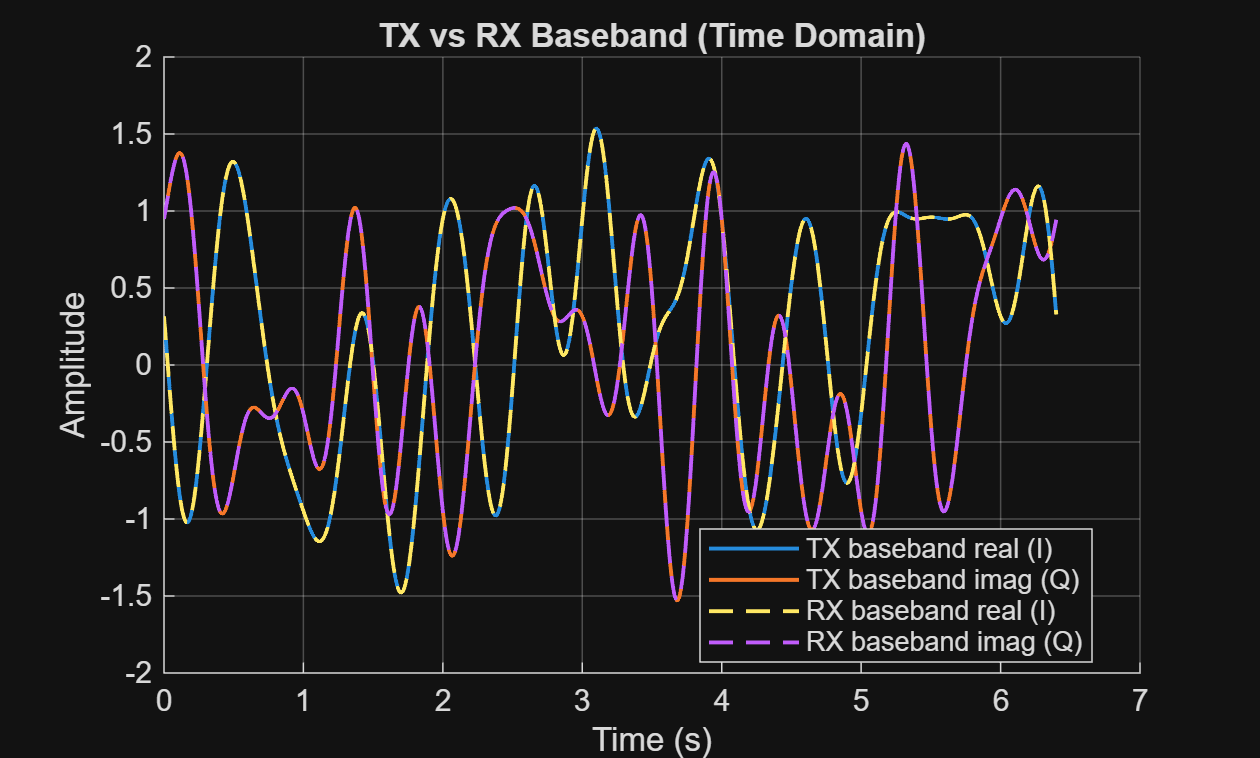


% --- Plot: four curves on one axes (full duration) ---
figure; hold on; grid on;
plot(tSamp, real(Sig_BB_TX_Upsamp), 'LineWidth', 1.3);
plot(tSamp, imag(Sig_BB_TX_Upsamp), 'LineWidth', 1.3);
plot(tSamp, real(Sig_downconv_lowpassed), '--', 'LineWidth', 1.3);
plot(tSamp, imag(Sig_downconv_lowpassed), '--', 'LineWidth', 1.3);
xlabel('Time (s)');
ylabel('Amplitude');
title('TX vs RX Baseband (Time Domain)');
legend('TX baseband real (I)', 'TX baseband imag (Q)', ...
       'RX baseband real (I)', 'RX baseband imag (Q)', ...
       'Location', 'best');

The RMSE between the original signal and downconverted+lowpass filtered signal is super small -> 0.

And their time domain signals overlap.

## (10) Downsampling

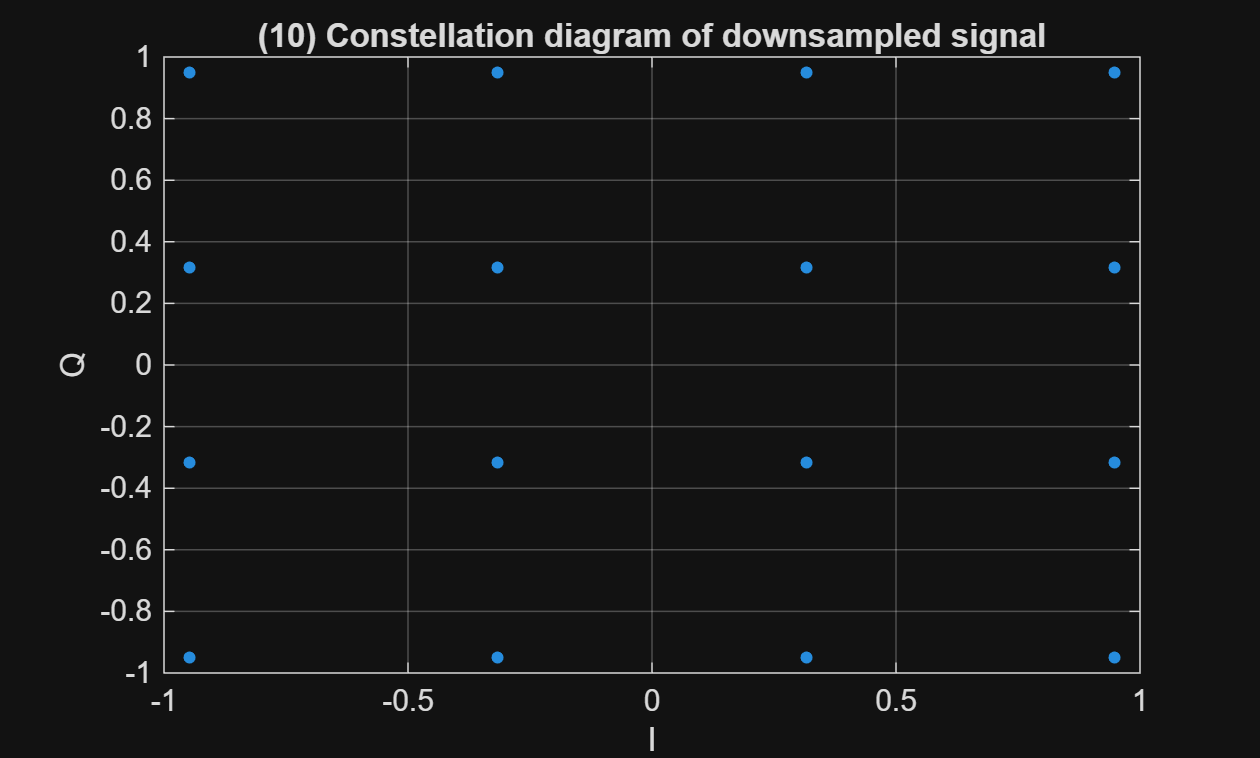

Sig_downsampled = downsample(Sig_downconv_lowpassed, (1000/5));
figure; grid on; 
plot(real(Sig_downsampled), imag(Sig_downsampled), '.', "MarkerSize", 12);
grid on;
xlabel('I')
ylabel('Q')
title('(10) Constellation diagram of downsampled signal')

## Additive noise

## (11) Power of the Signals

P_sym = mean(abs(Sym_TX).^2);
P_BB  = mean(abs(Sig_BB_TX_Upsamp).^2);

fprintf('Power of Sym_TX:           %.6f\n', P_sym);

Power of Sym_TX:           1.175000


fprintf('Power of Sig_BB_TX_Upsamp: %.6f\n', P_BB);

Power of Sig_BB_TX_Upsamp: 1.175000


Why is the power not exactly 1?

Because we're using only 32 symbols, and there are some symbols that appears more frequently than others.

The following assumes a equal probability to all constellation points. The $\sqrt{10}$  in denominator is for normalization.

levels = [-3 -1 1 3];
[Igrid, Qgrid] = ndgrid(levels, levels);
S_all = (Igrid(:) + 1j*Qgrid(:))/sqrt(10);

P_theory = mean(abs(S_all).^2); 
fprintf('Theoretical avg power over all 16 points: %.12f\n', P_theory);

Theoretical avg power over all 16 points: 1.000000000000


## (12) Noise power given SNR


$$SNR = \frac{P_{signal}}{P_{noise}} \rightarrow P_{noise} = \frac{P_{signal}}{SNR} = \frac{1}{10^2}=0.01$$


## (13) Noise power after downconversion and lowpass filtering

Donwconversion: All signals are multiplied by 2 -> Noise * 2^2

Lowpass filtering: The noise preserved is proportional to the lowpass filter BW to the whole frequency range assuming an ideal lowpass filter.

Final Noise = $\sigma^2 \times 2^2 \times \frac{f\_cutoff}{Fs/2}$, here Fs = 1000

## (14) Noise target

P_avg_signal = 1;
P_noise_target = P_avg_signal/100;
% here we choose f_cutoff to be the tightest value from (6)
cutoff = 2.5;
P_noise_AWGN = P_noise_target/4/cutoff * 500;
sigma = sqrt(P_noise_AWGN);
fprintf('sigma = %.4f\n', sigma);

sigma = 0.7071


## (15) AWGN implementation

rng(1);
n_awgn = sigma * randn(N,1);  

P_noise_emp = mean(n_awgn.^2);
fprintf('Empirical noise power: %.6f (target sigma^2 = %.6f)\n', P_noise_emp, sigma^2);

Empirical noise power: 0.506621 (target sigma^2 = 0.500000)


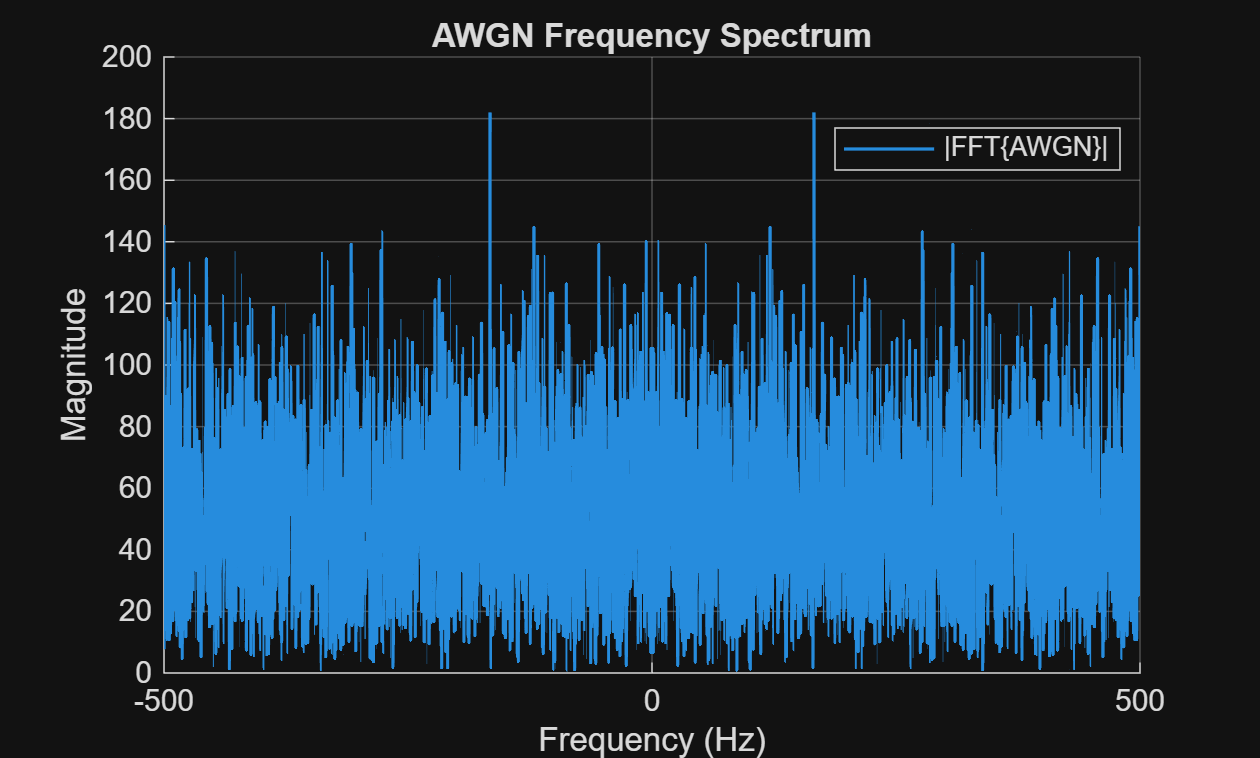


f = (-N/2:N/2-1) * (Fs/N);
Nspec = fftshift(fft(n_awgn));        

figure; hold on; grid on;
plot(f, abs(Nspec), 'LineWidth', 1.1, 'DisplayName','|FFT\{AWGN\}|');
xlim([-500 500]);                       % full band for Fs=1000 Hz
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('AWGN Frequency Spectrum');
legend('Location','best');

## (16) Constellation map with noise

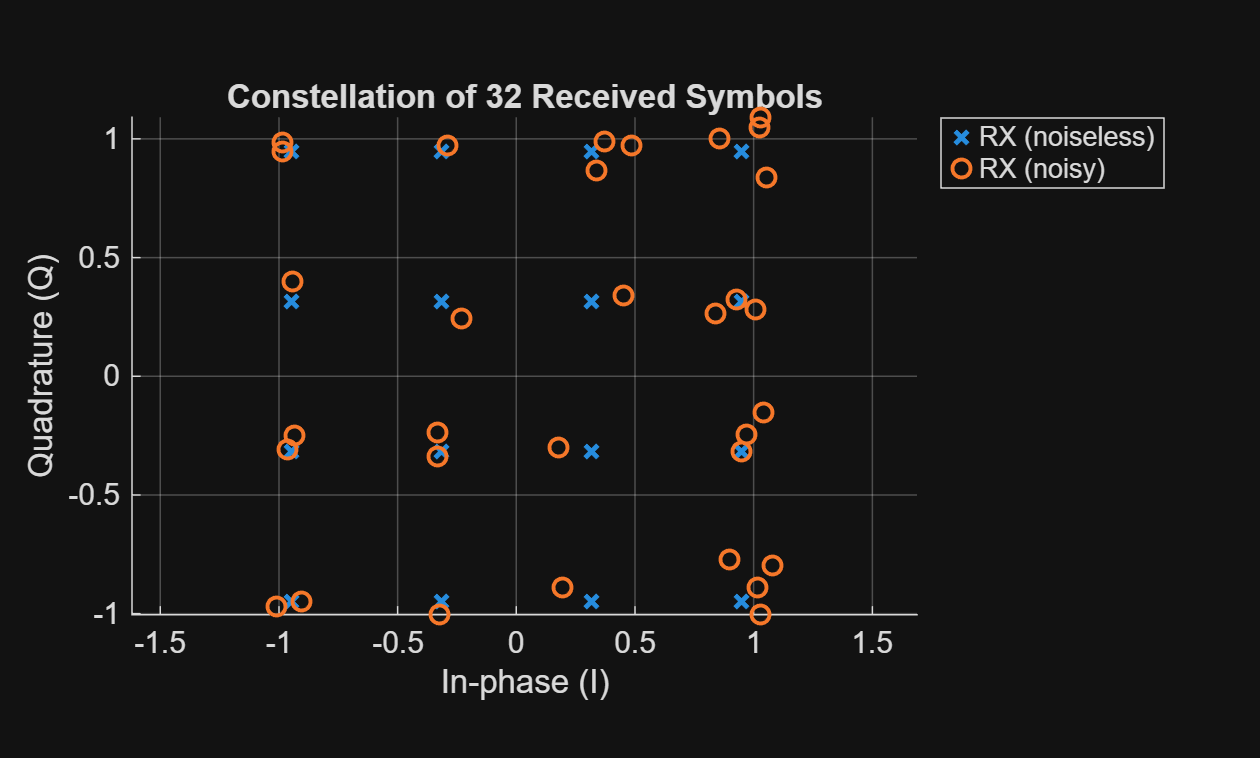

samples_per_symbol  = round(Fs/Rs);

Sig_noisy_upconv_real = Sig_upconv_real + n_awgn;

Sig_noisy_downconv = (Sig_noisy_upconv_real) .* exp(-1j*2*pi*fc*tSamp).' * 2;

f = (-N/2:N/2-1) * (Fs/N);
X_sig_noisy_downconv = fftshift(fft(Sig_noisy_downconv));
cutoff_mask = (abs(f) <= cutoff);
X_sig_noisy_downconv_lowpassed = X_sig_noisy_downconv .* cutoff_mask.';
Sig_noisy_downconv_lowpassed = ifft(ifftshift(X_sig_noisy_downconv_lowpassed));
Sig_noisy_downsampled = downsample(Sig_noisy_downconv_lowpassed, samples_per_symbol);

% ==== Plot constellations ====
figure; hold on; grid on; axis equal;
plot(real(Sig_downsampled), imag(Sig_downsampled), 'x', 'LineWidth', 1.6, 'DisplayName','RX (noiseless)');
plot(real(Sig_noisy_downsampled), imag(Sig_noisy_downsampled), 'o', 'LineWidth', 1.3, 'DisplayName','RX (noisy)');
xlabel('In-phase (I)');
ylabel('Quadrature (Q)');
title(sprintf('Constellation of 32 Received Symbols'));
legend('Location','northeastoutside');

## (17) Noise for each received symbol

Sig_noise = Sig_noisy_downsampled - Sig_downsampled;
P_noise_emp = mean(abs(Sig_noise).^2);
fprintf("Empirical noise power of the received symbols = %f\n", P_noise_emp);

Empirical noise power of the received symbols = 0.011759



SNR_emp = 10*log10(P_BB/P_noise_emp);
fprintf("Empirical SNR = %.4f dB", SNR_emp);

Empirical SNR = 19.9968 dB

# Part 2

## (1) 16-QAM Gary coding SNR=10dB

M = 16;
k = log2(M);
SNRdB = 10;
SNRlin = 10^(SNRdB/10);

Nb = 1e6;  % number of bits
Ns = Nb / k; % number of symbols
bits = randi([0 1], Nb, 1);

% modulation
bitMat = reshape(bits, k, Ns).';  % Ns x k
weights = 2.^(k-1:-1:0);
symIdx = bitMat * weights.';  % Ns x 1 decimal indices
Sig_random = qammod(symIdx, M, 'gray', 'UnitAveragePower', true);

% Confirm average power ~ 1
Px = mean(abs(Sig_random).^2);

NoiseVar = Px / SNRlin;
sigma = sqrt(NoiseVar); 
sigma_per_dim = sqrt(NoiseVar/2); 

fprintf('Average signal power Px = %.4f\n', Px);

Average signal power Px = 1.0002


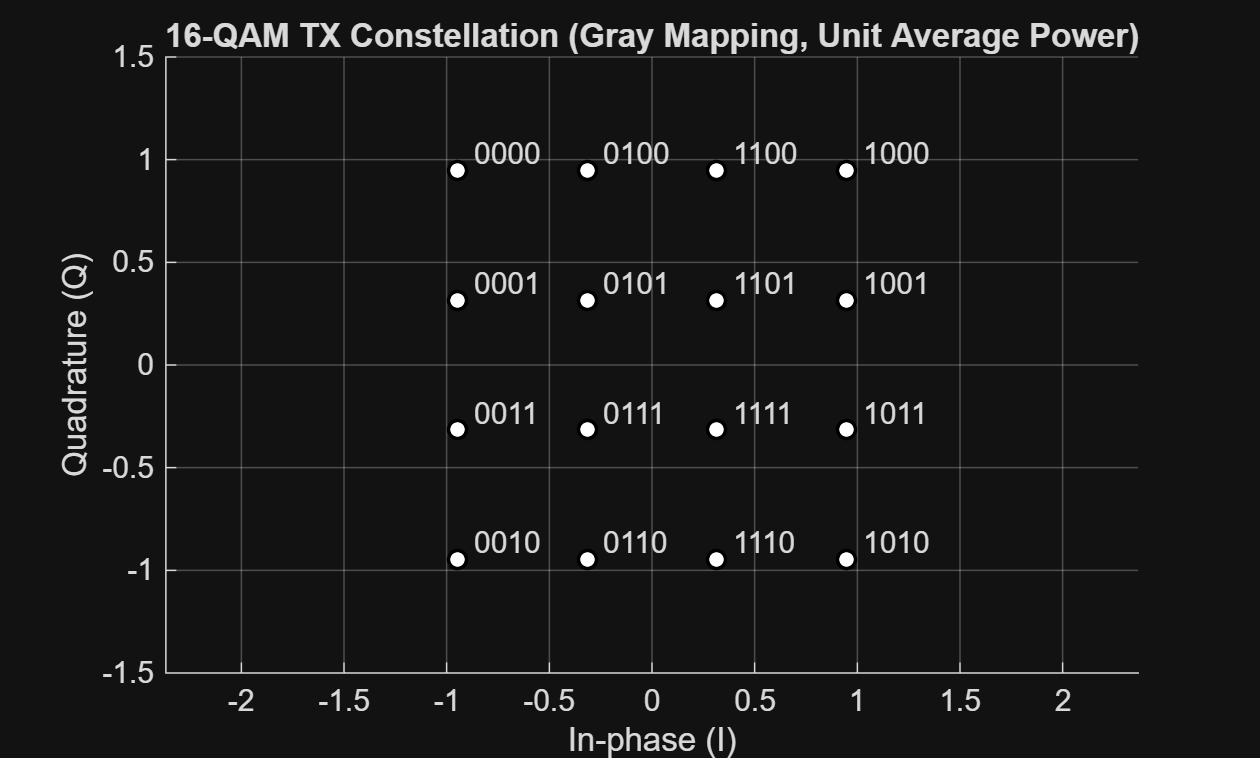

%AWGN
n = sigma_per_dim * (randn(Ns,1) + 1j*randn(Ns,1));
Sig_noisy_random = Sig_random + n; 

refConst = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);

%demodulation
label_bits = qamdemod(refConst, M, 'gray', 'UnitAveragePower', true, 'OutputType','bit'); 
% Reshape to M-by-k and convert to '0'/'1' chars for labeling
label_bits_matrix = reshape(label_bits, k, []).';
label_string = char(label_bits_matrix + '0');

% Plot constellation and annotate with Gray bit strings
figure; hold on; grid on; axis equal;
plot(real(refConst), imag(refConst), 'ko', 'MarkerFaceColor','w', 'LineWidth',1.2);
for m = 1:M
    text(real(refConst(m))+0.08, imag(refConst(m))+0.08, label_string(m,:), 'FontSize', 10);
end
xlabel('In-phase (I)'); ylabel('Quadrature (Q)');
ylim([-1.5, 1.5]);

title('16-QAM TX Constellation (Gray Mapping, Unit Average Power)');

Variance value for SNR=10dB = $\sqrt{1/10} = 0.2236$ (need both real and imagenary part)

## (2) Empirical powers for signal and noise

P_sig_emp = mean(abs(Sig_random).^2);
P_noise_emp = mean(abs(n).^2);
SNR_emp = 10*log10(P_sig_emp/P_noise_emp);

fprintf("(a) empirical signal power = %.4f", P_sig_emp);

(a) empirical signal power = 1.0002

fprintf("(b) empirical noise power = %.4f", P_noise_emp);

(b) empirical noise power = 0.1004

fprintf("(c) Empirical SNR = %.4f dB\n", SNR_emp);

(c) Empirical SNR = 9.9834 dB


## (3) Bit error rate

rx_bits = qamdemod(Sig_noisy_random, M, 'gray', 'UnitAveragePower', true, 'OutputType', 'bit');
nErrors = sum(bits ~= rx_bits);
BER = nErrors / length(bits);
fprintf("Bit Error rate = %.4f", BER);

Bit Error rate = 0.0593

## (4) Natural coding

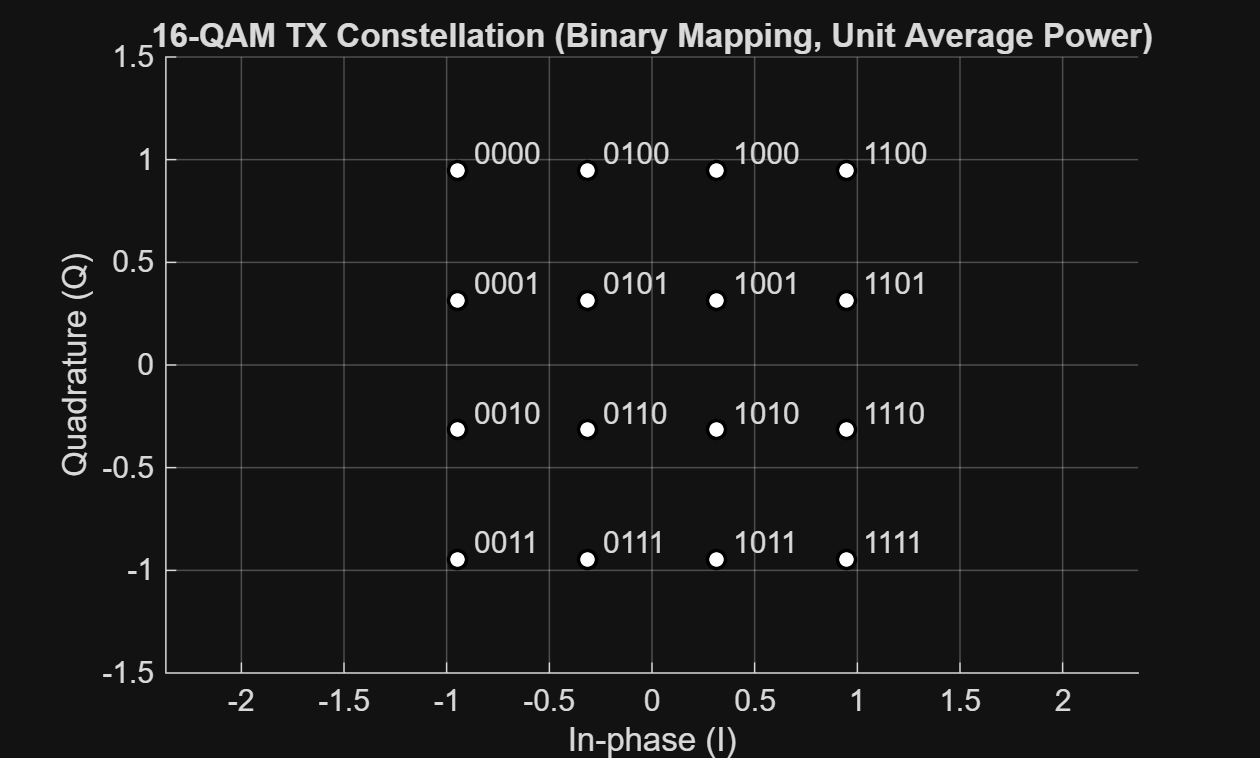

refConst_binary = qammod(0:M-1, M, 'bin', 'UnitAveragePower', true);

%demodulation
label_bits_binary = qamdemod(refConst_binary, M, 'bin', 'UnitAveragePower', true, 'OutputType','bit'); 
% Reshape to M-by-k and convert to '0'/'1' chars for labeling
label_bits_binary_matrix = reshape(label_bits_binary, k, []).';
label_string_binary = char(label_bits_binary_matrix + '0');

% Plot constellation and annotate with Gray bit strings
figure; hold on; grid on; axis equal;
plot(real(refConst_binary), imag(refConst_binary), 'ko', 'MarkerFaceColor','w', 'LineWidth',1.2);
for m = 1:M
    text(real(refConst_binary(m))+0.08, imag(refConst_binary(m))+0.08, label_string_binary(m,:), 'FontSize', 10);
end
xlabel('In-phase (I)'); ylabel('Quadrature (Q)');
ylim([-1.5, 1.5]);

title('16-QAM TX Constellation (Binary Mapping, Unit Average Power)');

## (5) Bit error rate for natural coding

Sig_random_binary = qammod(symIdx, M, 'bin', 'UnitAveragePower', true);
Sig_random_binary_noisy = Sig_random_binary + n;
rx_bits_binary = qamdemod(Sig_random_binary_noisy, M, 'bin', 'UnitAveragePower', true, 'OutputType', 'bit');
nErrors_binary = sum(bits ~= rx_bits_binary);
BER_binary = nErrors_binary / length(bits);
fprintf("Bit Error rate = %.4f", BER_binary);

Bit Error rate = 0.0793

## (6) Binary code vs Gray code

In the case of gray coding, if a symbol is decoded incorrectly, there is a very high chance that only 1 bit will be flipped. In contrast, the neighboring symbols in binary code may be different by more than one bit, and thus having more error in the decoded bit string.

## (7) Random bit string generation

Strategy: Generate a uniform random number sequency between 0~1, and if the number < 0.1, the corresponding bit is 0, and the bit is 1 if >= 0.1.

Nb = 1e6; 
p0 = 0.1;    
u = rand(Nb,1);  
bits = (u >= p0);             
pct0 = sum(bits==0)/Nb * 100;
fprintf('Percentage of 0s = %.2f%%\n', pct0);

Percentage of 0s = 10.01%


## (8) BPSK for SNR=5dB

SNRdB = 5;
SNRlin = 10^(SNRdB/10);
NoiseVar = Px / SNRlin;
NoiseVar_per_dim = NoiseVar/2;
fprintf("Variance value = %.4f", NoiseVar_per_dim);

Variance value = 0.1581

## (9) BPSK simulation

Sig_BPSK = 1 - 2*bits;  %(0, 1) -> (1, -1)
Sig_BPSK = complex(Sig_BPSK, 0);

sigma_per_dim    = sqrt(NoiseVar_per_dim);  % ≈ 0.398
n = sigma_per_dim*(randn(Nb,1) + 1j*randn(Nb,1));  % complex AWGN
Sig_BPSK_noisy = Sig_BPSK + n;

P_sig_emp   = mean(abs(Sig_BPSK).^2); 
P_noise_emp = mean(abs(n).^2);
SNR_emp_dB  = 10*log10(P_sig_emp / P_noise_emp);
fprintf('Empirical P_signal = %.4f, P_noise = %.4f, SNR = %.2f dB\n', P_sig_emp, P_noise_emp, SNR_emp_dB);

Empirical P_signal = 1.0000, P_noise = 0.3164, SNR = 5.00 dB


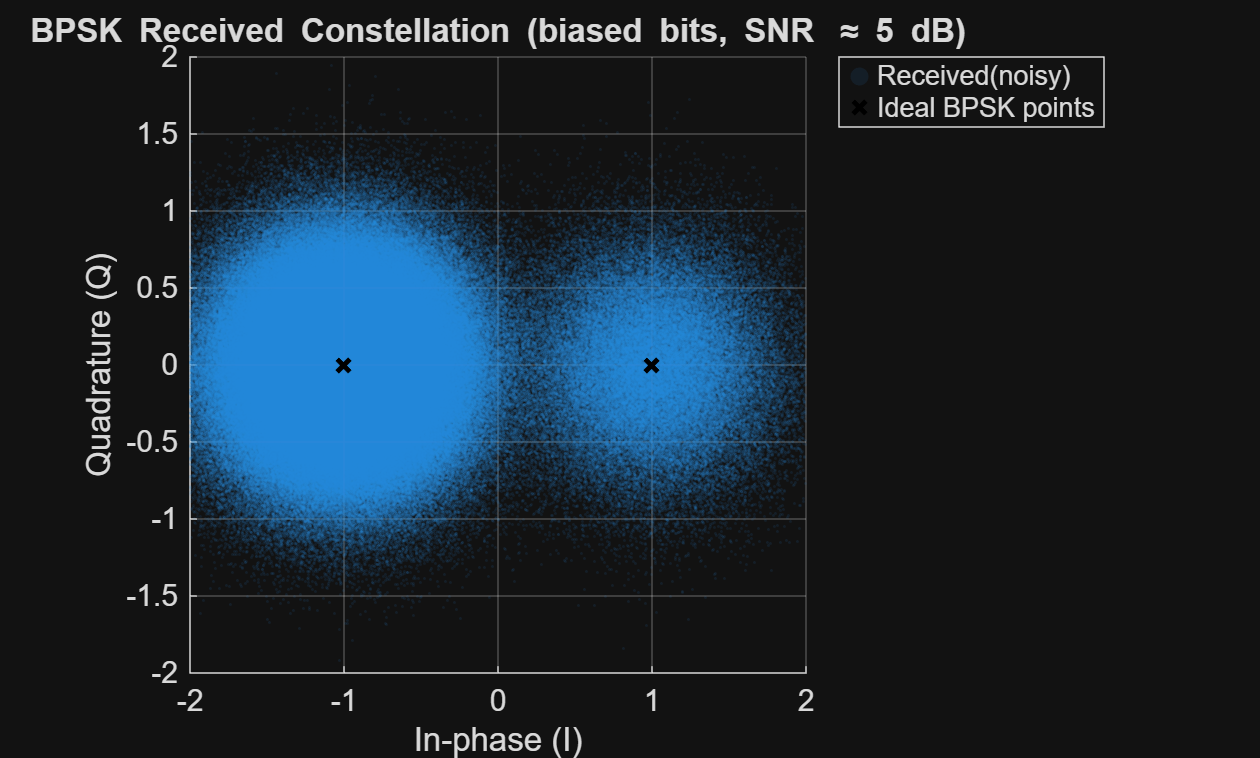


% --- Plot received constellation (unbalanced) ---
figure; hold on; grid on; axis equal;
scatter(real(Sig_BPSK_noisy), imag(Sig_BPSK_noisy), 1, 'filled', 'MarkerFaceAlpha', 0.1, 'MarkerEdgeAlpha', 0.1, 'DisplayName','Received(noisy)');
plot([-1 1], [0 0], 'kx', 'LineWidth', 1.6, 'DisplayName','Ideal BPSK points');
xlabel('In-phase (I)'); ylabel('Quadrature (Q)');
title('BPSK Received Constellation (biased bits, SNR \approx 5 dB)');
legend('Location','northeastoutside');
xlim([-2 2]); ylim([-2 2]);

## (10) BER for decoding with ML rule

Sig_decoded_ML = real(Sig_BPSK_noisy) < 0; 
BER_ML_emp = mean(Sig_decoded_ML ~= bits); 
fprintf('Empirical BER (ML) = %.4f\n', BER_ML_emp);

Empirical BER (ML) = 0.0059


## (11) MAP rule boundary


$$\delta_{MAP}(y) = arg \min {||y-s_i||^2-2\sigma^2\log{\pi_i}}$$



$${||y-s_0||^2-2\sigma^2\log{\pi_0}} < {||y-s_1||^2-2\sigma^2\log{\pi_1}}$$



$$||y-s_0||^2 - ||y-s_1||^2  < 2\sigma^2\log{\pi_0} - 2\sigma^2\log{\pi_1}$$



$$(I-1)^2+Q^2 -(I+1)^2-Q^2 <  2\sigma^2\log{\frac{\pi_0}{\pi_1}}$$



$$-4I < 2\sigma^2\log{\frac{\pi_0}{\pi_1}}$$



$$I>-\frac{\sigma^2}{2}\log{\frac{\pi_0}{\pi_1}}$$


pi_0 = 0.1;
pi_1 = 0.9;
decision_boundary = - 0.5 * NoiseVar * log(pi_0/pi_1);
fprintf("decision boundary = %.4f\n", decision_boundary)

decision boundary = 0.3475


## (12) BER for decoding with MAP

Sig_decoded_MAP = real(Sig_BPSK_noisy) < decision_boundary; 
BER_MAP_emp = mean(Sig_decoded_MAP ~= bits); 
fprintf('Empirical BER (MAP) = %.4f\n', BER_MAP_emp);

Empirical BER (MAP) = 0.0053


## (13) BER comparison

fprintf('Empirical BER (ML) = %.4f\n', BER_ML_emp);

Empirical BER (ML) = 0.0059


fprintf('Empirical BER (MAP) = %.4f\n', BER_MAP_emp);

Empirical BER (MAP) = 0.0053


MAP has better BER than ML because MAP also consider the probability of a bit being transmitted.

(We can also intuitively see from the scattering plot that the boundary between -1 and 1 is greater than 0)